# Wireless Communications Project ( Lab 9)

### Ray Tracing Data 

We have dataset from raytracing performed in a indoor environment. We will get the positions of the RX and the TX antennas. 

load("roomPathData.mat")


Getting the TX and RX positions from the data set. 


rxPos = pathData.rxPos;
txPos = pathData.txPos;
rxPosInd =pathData.rxPosInd;
txPos = txPos';
nRx = length(rxPos);
nTx = length(txPos);
aoaAz = pathData.aoaAz;
aodAz = pathData.aodAz;
aoaEl = pathData.aoaEl;
aodEl = pathData.aodEl;
dly = pathData.dly;
gain = pathData.gain;
fc = pathData.fc;
pl = pathData.pl;
linkState = pathData.linkState;

Selecting a random RX location from the dataset. We can run this several times to get the different locations. 

Rxrand = randi(nRx);
RxLocInd = [rxPosInd(Rxrand,1) rxPosInd(Rxrand,2)];
RxLoc = [rxPos(Rxrand,1) rxPos(Rxrand,2)];

We will now get the channel data between the transmitter and current receiver. 

aoaAz = aoaAz(Rxrand,:)';
aodAz = aodAz(Rxrand,:)';
aoaEl = aoaEl(Rxrand,:)';
aodEl = aodEl(Rxrand,:)';
dly = dly(Rxrand,:)';
gain = gain(Rxrand,:)';
fc = pathData.fc;
pl = pl(Rxrand,:)';
linkState = linkState(Rxrand,:)';


Plotting the location of transmitter and receiver. 

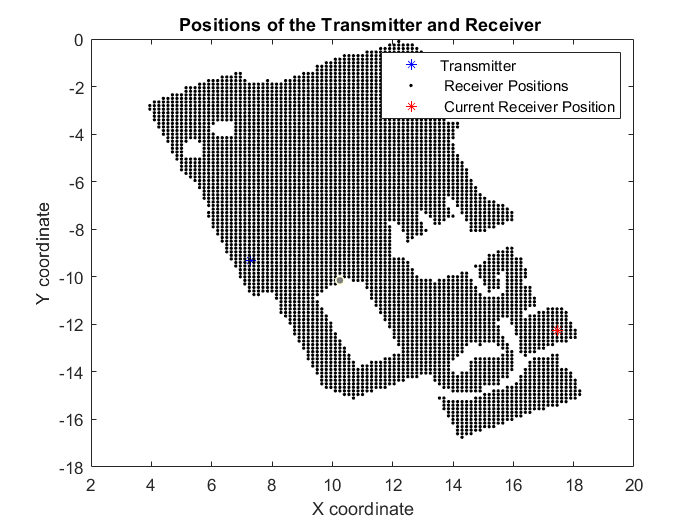

figure;

plot(txPos(1,1),txPos(1,2),"LineStyle","none","Marker","*","Color",'b')
hold on 
plot(rxPos(:,1),rxPos(:,2),"LineStyle","none","Marker",".","Color",'k')
hold on 
plot(RxLoc(1,1),RxLoc(1,2),"LineStyle","none","Marker","*","Color","r")
hold off
title("Positions of the Transmitter and Receiver ")
legend("Transmitter"," Receiver Positions", " Current Receiver Position")

xlabel("X coordinate")
ylabel("Y coordinate")

Since all the paths don't have a LOS for a given receiver position , we will calculate the number of LOS paths. 

% getting the LOS and NLOS paths
los = 25 - sum(isnan(gain));
fprintf("Number of LOS path : %d", los)

Number of LOS path : 25

The gain plot will have only the LOS paths since there is no defined gain on the Blocked paths.

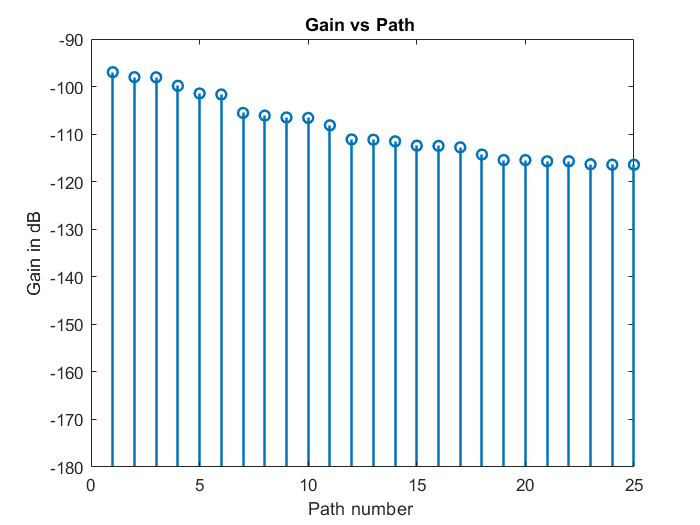

%plotting the gain vs path 
stem(gain,"BaseValue",-180,'LineWidth',1.5)
title('Gain vs Path ')
xlabel('Path number ')
ylabel('Gain in dB')

### Creating antenna element

In this part we are creating the antenna element , which will be a patch element.

elem = design(patchMicrostrip, fc);

The element is constructed with the boresight in the positive z-axis. we will rotate it. 

elem.Tilt = 90;
elem.TiltAxis = [0 1 0];

Showing the element in the normal position and its directivity. 

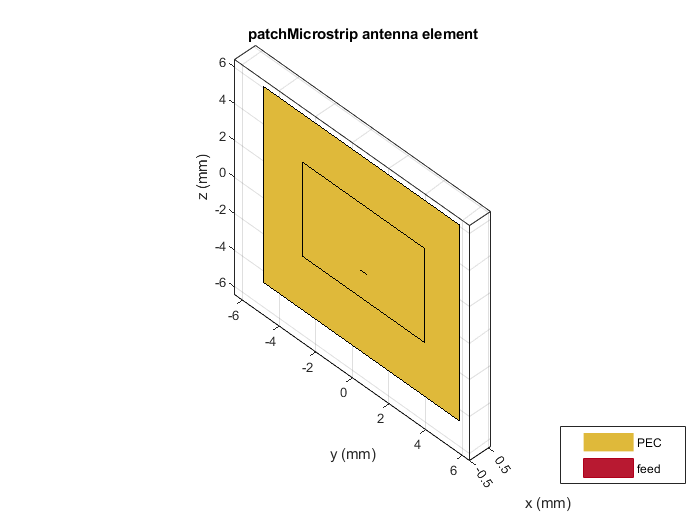

elem.show();
view(45,-45);

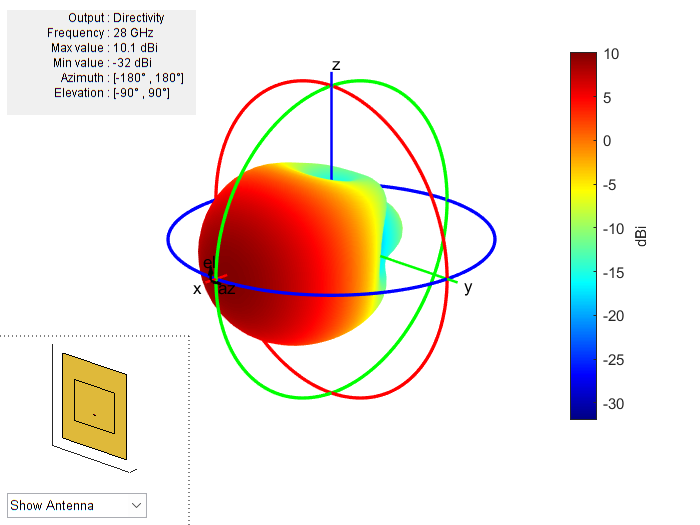


elem.pattern(fc);

### Creating the antenna arrays

Creating the antenna arrays as done in labs. I am changing  the number of elements.

% Number of antennas 
nantgNB = [4,4];
ntx = 4*4;
nrx = 2*2;
nantUE = [2,2];
lambda = physconst('lightspeed')/fc;


  arrgNB = phased.URA(nantgNB,0.5*lambda,'ArrayNormal',"x");
   arrUE = phased.URA(nantUE,0.5*lambda,"ArrayNormal","x");

### Array Platform 

This is done with a helper function from labs  : ArrayPlatform.

arrPlatformgNB = ArrayPlatform('elem', elem, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();


arrPlatformUE =  ArrayPlatform('elem', elem, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();


Displaying the array patterns for different steering angles. 

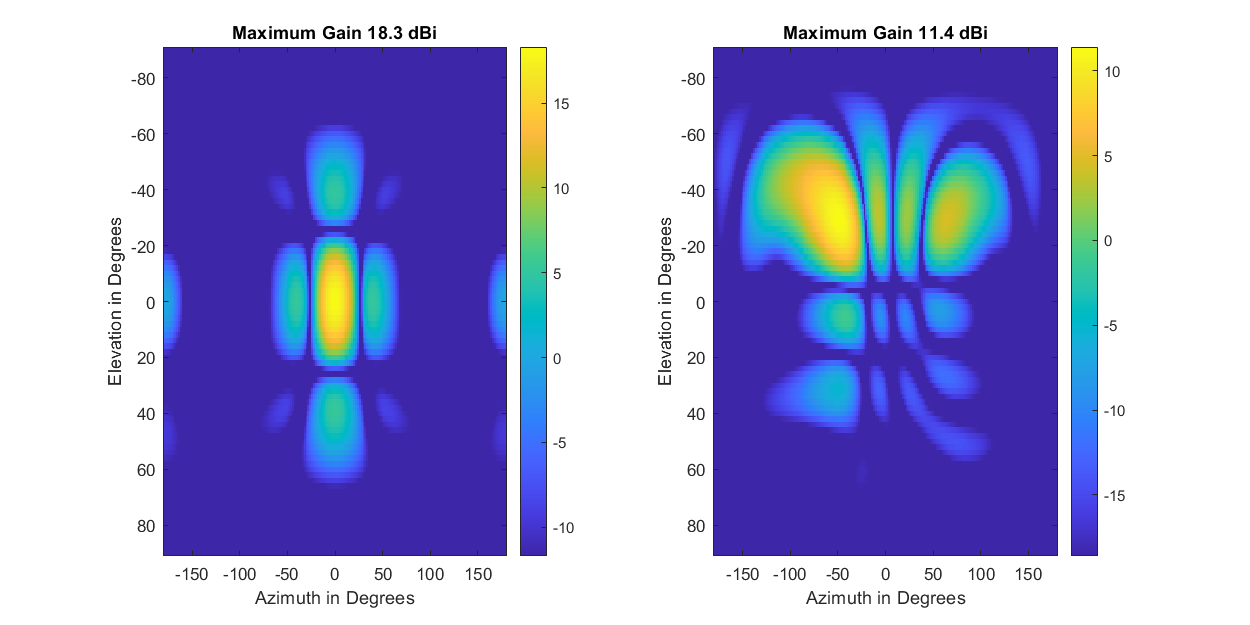

% Angles to get the beamforming vectors
az0 = [0, -60]';
el0 = [0, -30]';
nw = length(az0);

svTx = arrPlatformgNB.step(az0, el0);
  
wNorm = conj(svTx);
w = wNorm / norm(wNorm);


% Angles to plot the array pattern
az = (-180:2:180)';
el = (-90:2:90)';
naz = length(az);
nel = length(el);

% Getting  grid of values
[azMat, elMat] = meshgrid(az, el);
azVal = azMat(:);
elVal = elMat(:);

Sv = arrPlatformgNB.step(azVal, elVal);

clf;
figure;
posOld = get(gcf, 'Position');
set(gcf,'Position', [0,0,1000,500]);

% Loop over the beamforming vectors
for i = 1:nw
    
            
   
    gain_arr = mag2db(abs(sum(w(:,i).*Sv)));
   
     % Finding  the maximum gain 
    
    gainMax = max(gain_arr);
    
    gain_arr = reshape(gain_arr, [nel,naz]);    
    
    
    % Ploting  the gain on a subplot. using imagesc()
    
    clim = [gainMax-30, gainMax];
  
    subplot(1,nw,i);
    imagesc(az, el, gain_arr, clim);
    colorbar();
    xlabel('Azimuth in Degrees');
    ylabel('Elevation in Degrees');
    title(sprintf('Maximum Gain %3.1f dBi', gainMax));
    
end

### Gain along the paths 

Here I am getting the gains along the paths for the given receiver. 

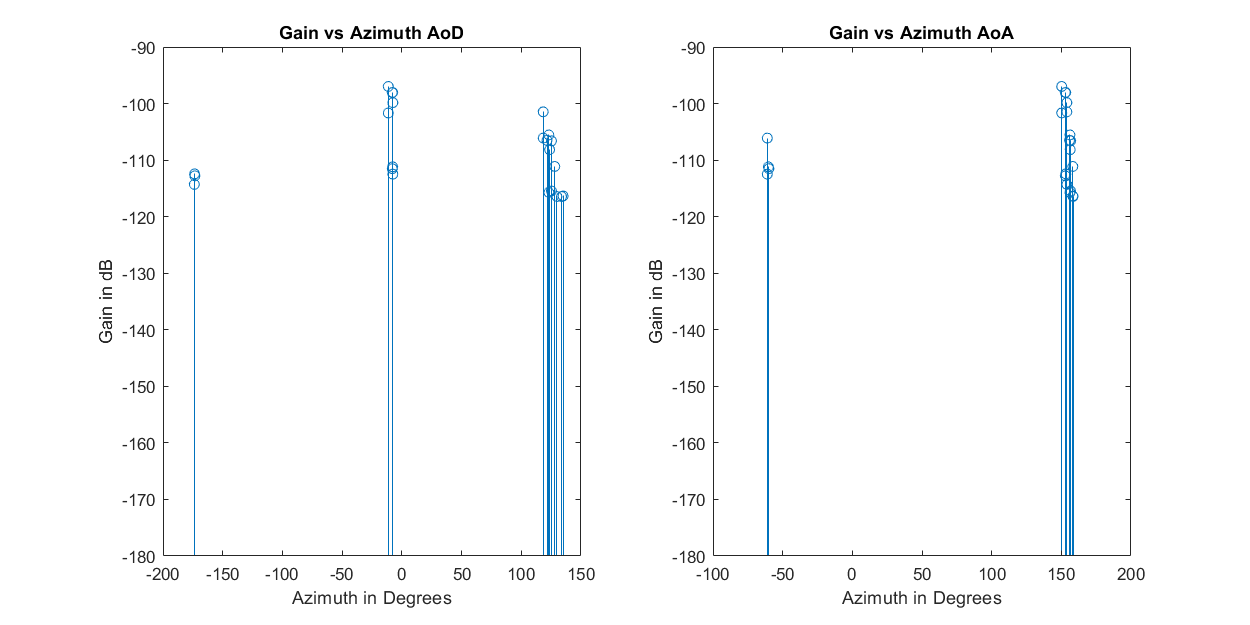

clf; 
set(gcf,'Position', [0,0,1000,500]);
subplot(1,2,1)
stem(aodAz, gain, 'BaseValue', -180);
title('Gain vs Azimuth AoD')
xlabel('Azimuth in Degrees')
ylabel('Gain in dB')
subplot(1,2,2)
stem(aoaAz, gain, 'BaseValue', -180);
title('Gain vs Azimuth AoA')
xlabel('Azimuth in Degrees')
ylabel('Gain in dB')

Now rotating the UE according to the maximum paths gains at the angle of arrival .

azUE = 150;
elUE = -10;
arrPlatformUE.alignAxes(azUE, elUE);

Next, getting the TX element gains and steering vectors along the AoD and the RX element gains and steering vectors along the AoAs.

[svTx, elemGainTx] = arrPlatformgNB.step(aodAz, aodEl);
[svRx, elemGainRx] = arrPlatformUE.step(aoaAz, aoaEl);

Getting the gains along the paths with the element gains but without any array gain.  

                  
gainElem = gain + mag2db(elemGainTx) + mag2db(elemGainRx);         

Plotting to show the gains in the path due to alignment of arrays. 

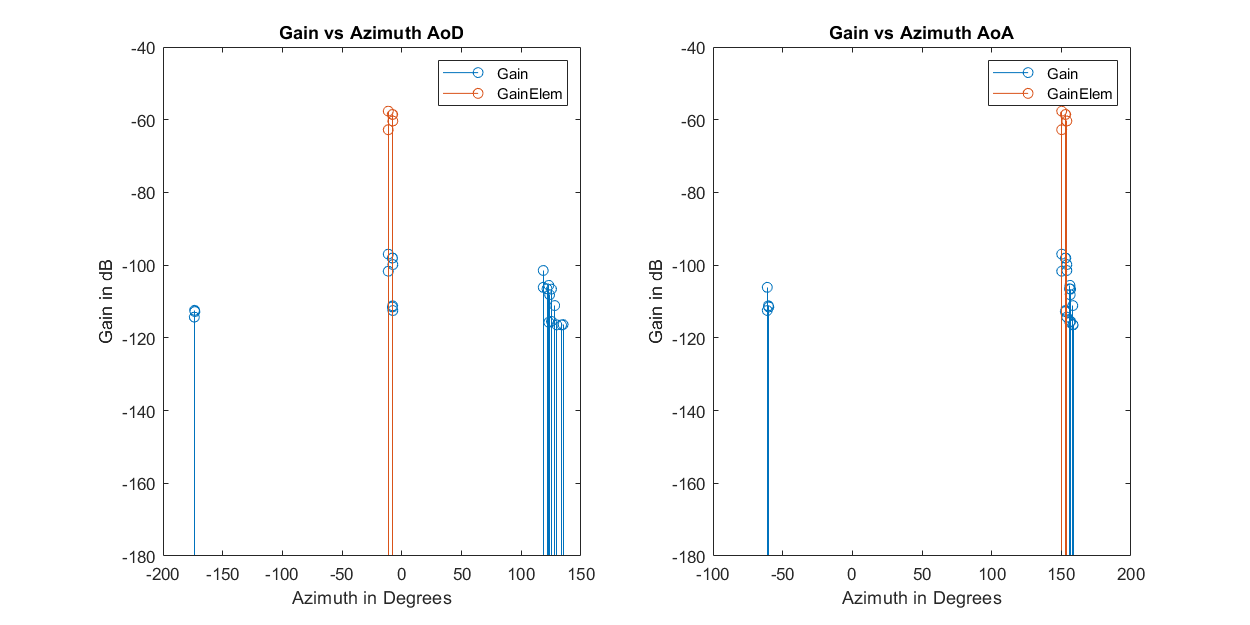


clf; 
set(gcf,'Position', [0,0,1000,500]);
subplot(1,2,1)
stem(aodAz, gain, 'BaseValue', -180);
hold on;
stem(aodAz, gainElem, 'BaseValue', -180);
hold off;
title('Gain vs Azimuth AoD')
xlabel('Azimuth in Degrees')
ylabel('Gain in dB')
legend('Gain','GainElem')

subplot(1,2,2)
stem(aoaAz, gain, 'BaseValue', -180);
hold on;
stem(aoaAz, gainElem, 'BaseValue', -180);
hold off;
title('Gain vs Azimuth AoA')
xlabel('Azimuth in Degrees')
ylabel('Gain in dB')
legend('Gain','GainElem')

### Creating the channel 

We will create the channel in frequnecy to see the effects of the beamforming. 

 
SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 51;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB
nsc = NRB*nscPerRB;
nsym = 14;

Getting the configurations :

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);


## Configuring the DM-RS and PDSCH 

Here we will configure the reference and the data signals on the PDSCH

%  Set the DM-RS config
dmrsConfig = nrPDSCHDMRSConfig(...
       'NumCDMGroupsWithoutData', 1, ...  % No unused DM-RS
       'DMRSAdditionalPosition', 1, ...   % Set this correctly
       'DMRSConfigurationType', 2);       % Set this correctly      

Given the DM-RS configuration, we set the PDSCH:


pdschConfig = nrPDSCHConfig();
pdschConfig.NSizeBWP = [];   % Empty implies that the value is equal to NSizeGrid
pdschConfig.NStartBWP = [];  % Empty implies that the value is equal to NStartGrid
pdschConfig.PRBSet = (0:NRB-1);   % Allocate the complete carrier
pdschConfig.SymbolAllocation = [0 14]; % Symbol allocation [S L]
pdschConfig.MappingType = 'A'; % PDSCH mapping type ('A' or 'B')
pdschConfig.EnablePTRS = true;
pdschConfig.PTRS =  nrPDSCHPTRSConfig();
pdschConfig.DMRS = dmrsConfig;

## Creating the gNB Transmitter

Creating the transmitter using the TX class : NRgNBTxFD

tx = NRgNBTxFD(carrierConfig, pdschConfig);
tx.step();

Plotting the channels.

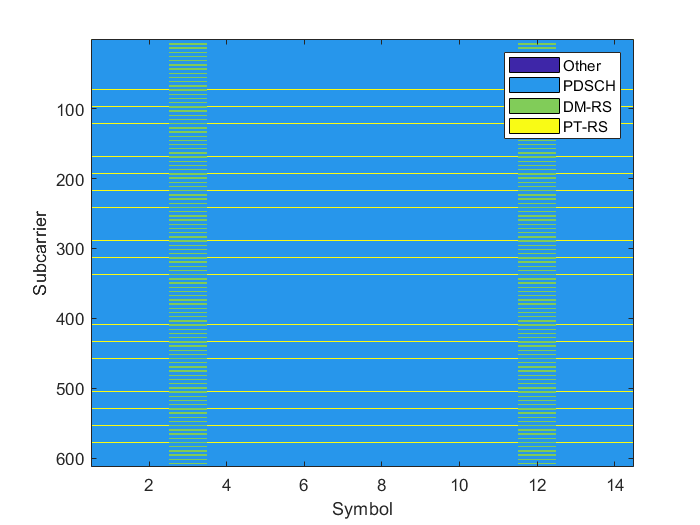

figure;
plotChan(tx.txGridChan, tx.chanNames);
xlabel("Symbol")
ylabel("Subcarrier")

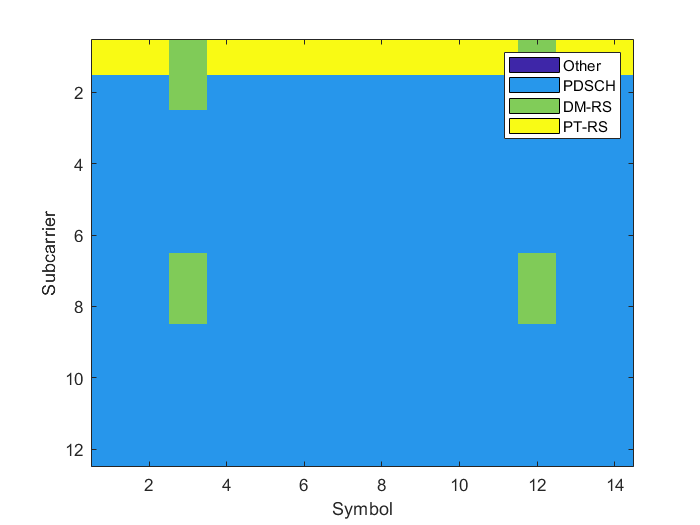



figure;
plotChan(tx.txGridChan(1:12,:),tx.chanNames)
xlabel("Symbol")
ylabel("Subcarrier")

## Visualizing the OFDM Channel

Using the MIMO channel class FDMIMOChan

Enoise = -5;  % Energy per noise sample in dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);


frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

Plotting SNR for the antenna pair (3,4) 

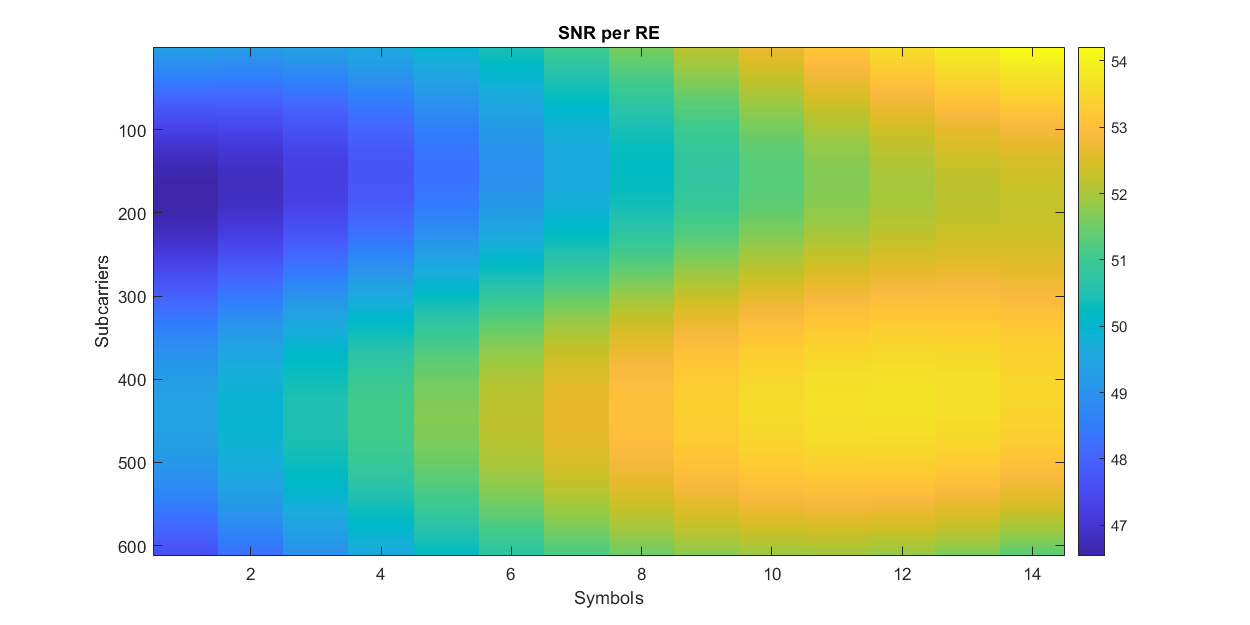


clf;
set(gcf,'Position', [0,0,1000,500]);
snrSing = mag2db(abs(chanGrid(3,4,:,:)).^2/noiseVar);

imagesc(reshape(snrSing,[nsc,nsym]));
title('SNR per RE')
xlabel('Symbols')
ylabel('Subcarriers')
colorbar();

% Creating TX and RX

tx = NRgNBTxFD(carrierConfig, pdschConfig);
rx = NRUERxFD(carrierConfig, pdschConfig);

% Running the TX
txGrid = tx.step();


Plotting the transmitted QPSK symbols 

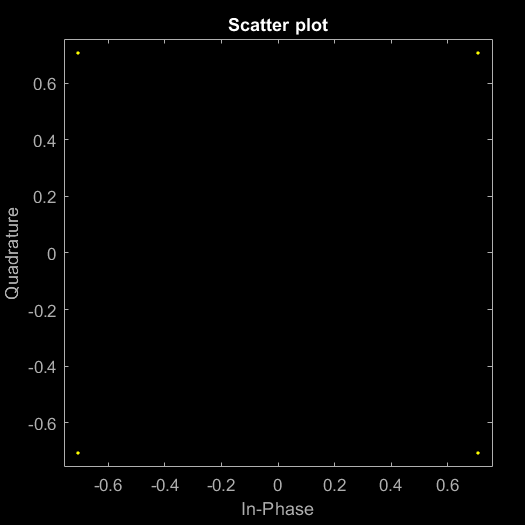

scatterplot(tx.pdschSym)

Applying the channel and the noise to the transmitted.I am using the channel for the antenna pair( 3,4 ). Although the whole rxGrid can be calculated but the output will be a 4D matrix for all the antenna pairs. 


chan = reshape(chanGrid(3,4,:,:),[nsc,nsym]);

% applying the channel to the transmitted symbols and adding noise 

rx_s =reshape(chanGrid(3,4,:,:),[nsc,nsym]).*txGrid + (randn(nsc,nsym) + 1i*randn(nsc,nsym))*sqrt(noiseVar/2);

% alternative way to calculate the rxGrid for all the antenna pairs

%for i = 1:4
%    for j =1:16
%        rxGrid(i,j,:,:) = reshape((reshape(chanGrid(i,j,:,:),[nsc,nsym]).*txGrid + (randn(nsc,nsym) + 1i*randn(nsc,nsym))*sqrt(noiseVar/2)),[1,1,732,14]);
        
 %   end
%end


Now we get the rxGrid for channel pair(3,4). Passing it through the RX we get the bits. The receiver implements the MMSE equilization but doesn't compute LLR . The bits are decoded with hard decision. 

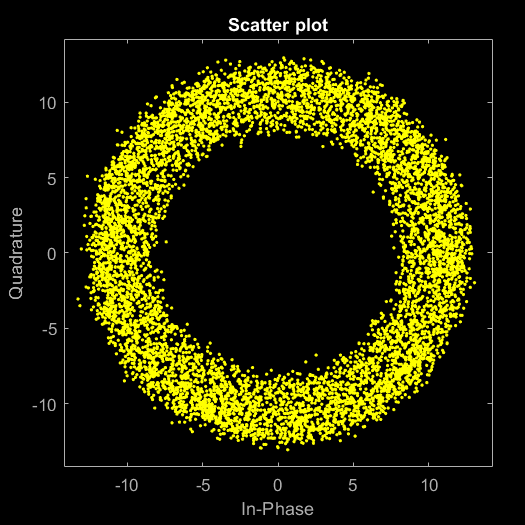


rx.step(rx_s,chan,noiseVar)

%plotting the received symbols on the PDSCH 

scatterplot(rx.pdschSym)


% getting the received bits 

rx_bits = rx.rxBits;

%calculating the Error rates 

ber= mean(rx_bits ~= tx.txBits);


## Channel Estimator 

Runnig the channel estimator on symbol 3 and 9 

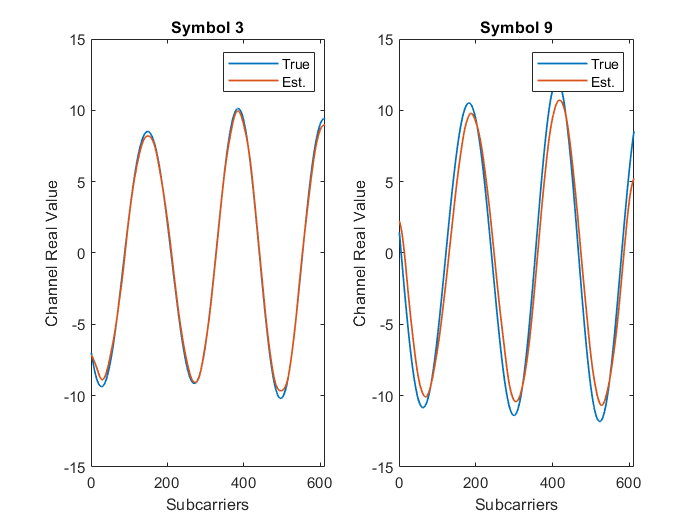


rx.chanEst(rx_s);

isymPlot = [3,9];

% TODO
chan_true = real([chan(:,3) chan(:,9)]);
chan_est = real([rx.chanEstGrid(:,3) rx.chanEstGrid(:,9)]);
figure;
subplot(1,2,1)
plot(chan_true(:,1),LineWidth=1)
hold on 
plot(chan_est(:,1),LineWidth=1)
hold off
title("Symbol 3")
legend("True","Est.")
xlabel("Subcarriers")
ylabel("Channel Real Value")
subplot(1,2,2)
plot(chan_true(:,2),LineWidth=1)
hold on 
plot(chan_est(:,2),LineWidth=1);
hold off
title("Symbol 9")
legend("True","Est.")
xlabel("Subcarriers")
ylabel("Channel Real Value")

The error in the estimation is :

mse = 10*log10(mean(abs(rx.chanEstGrid-chan).^2, 'all'));
fprintf('MSE = %7.2f\n', mse);

MSE =    5.96
